Produce plots of the following in Matlab.

- 
$$\mathrm{sin}\left(\mathrm{kx}\right)$$


- 
$$x^2$$


- $-a$ when $c<x<d$, otherwise $0$, where $a$ is an arbitrary number

x = linspace(-10, 10, 1000);

% Define first function
k = 10;
y1 = sin(k * x);

% Plot and decorate
subplot(2,2,1);
plot(x, y1, "r");
title("Function #1");
xlabel("x");
ylabel("y");
legend("y = sin(" + k + "x)");

% Define second function
y2 = x.^2;

% Plot and decorate
subplot(2,2,2);
plot(x, y2, "b");
title("Function #2");
xlabel("x");
ylabel("y");
legend("y = x^2");

% Define third function
syms y3(x) a c d
y3(x) = piecewise(c < x & x < d, -a, 0)

$$y3(x) = \left\{ \begin{array}{cl} -a & \text{ if }c<x\wedge x<d\\ 0 & \mathrm{otherwise} \end{array}\right.$$

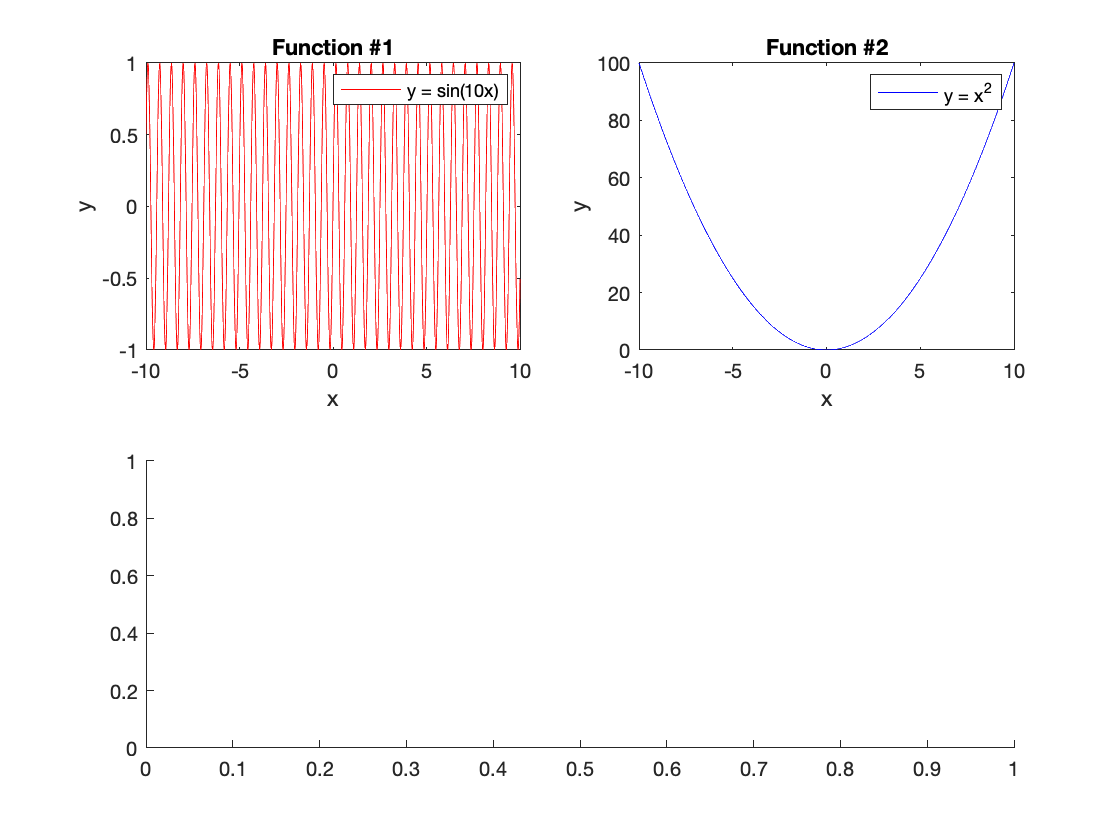

Error using fplot>singleFplot (line 240)
Input must be a function or functions of a single variable.

Error in fplot>@(f)singleFplot(cax,{f},limits,extraOpts,args) (line 200)
        hObj = cellfun(@(f) singleFplot(cax,{f},limits,extraOpts,args),fn{1},'UniformOutput',false);

Error in 


subplot(2,2,[3, 4]);
fplot(y3, "--")

title("Function #3");
xlabel("x");
ylabel("y");
legend("-a when c < x < d or else 0");